## 函数库

- Monte_Carlo

                InitialDirection: 围绕光纤周围定义初始随机位置

                isInCylinder*（未使用）*： 定义粒子在材料内计算  

                scatterDirection：散射方向

                        findPerpendicularVectors：寻找法线方向

                photon_path_length*（需要修改）*：光子自由程

- Heat_distribution：通过光子分布计算计算瞬时热量分布

                   注意：分布的边界选取需要修改

## Initialization parameters

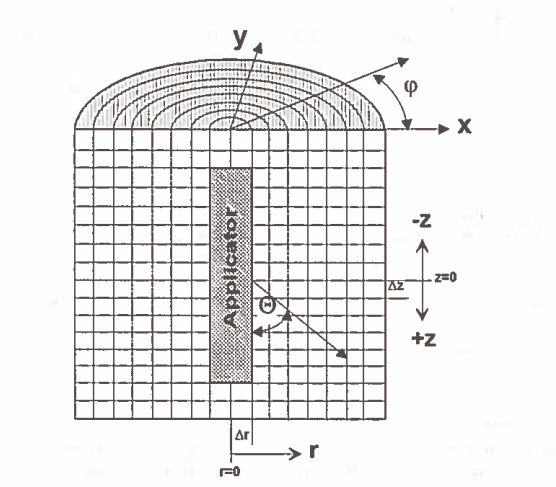

Absorption coefficient


$$P_{\text {absorption }}=1-\exp \left(-\mu_{\mathrm{a}} \Delta s\right)=\mu_{\mathrm{a}} \Delta \mathrm{s}$$


Scattering coefficient

$\mathrm{p}_{\text {scattering, } \mathrm{HG}}=1-\exp \left(-\mu_s \Delta \mathrm{s}\right)=\mu_s \Delta \mathrm{s}$; 

 $\mathrm{p}_{\text {sacattering, Iso }}=1-\exp \left(-\mu_3^{\prime} \Delta s\right) \approx \mu_3^{\prime} \Delta s$;

% Dimensional parameters
diameter = 1.8;          % 光纤直径
cylinder_length = 7;     % 光纤长度
Power=9;                 % 光纤功率
delta_t=0.1;             % 计算最小时长

% Monte_Carlo Calculation parameters
mu_a = 0.19;                % 吸收系数，单位1/mm
mu_s = 43.2 ;               % 约化散射系数，单位1/mm
g = 0.99;                   % 各向异性参数
mu_s_prime = mu_s * (1 - g);
mfp = 1 / (mu_a + mu_s_prime); % mean free path
delta_s = min(0.25, mfp / 1); % step size
Nphoton = 1e5;
power_per_photon=(Power*delta_t)/Nphoton;

## Monte_Carlo photon distribution calculation

#### BASIC PARAMETER

New angle after collision


$$\cos \Theta_{\text {ral }}=\frac{1}{2 g_{\mathrm{HO}}}\left(1+g_{\mathrm{HO}}^2-\left[\frac{1-g_{\mathrm{HO}}^2}{1+g_{\mathrm{HO}}-2 g_{\mathrm{HO}} \xi_2}\right]^2\right) \quad \varphi_{\text {rel }}=2 \pi \xi_3$$


#### New displacement after collision


$$\Delta s \leq \frac{1}{10 \cdot\left(\mu_1+\mu_1\right)}$$



$$\Delta \mathrm{s}=\Delta \mathrm{s} \cdot(1+0.25 \cdot(1-2 \xi))$$


absorbed_photons=Monte_Carlo(Nphoton, diameter, cylinder_length, mu_a, mu_s, mu_s_prime, delta_s, mfp, g);
X = absorbed_photons(:,1);
Y = absorbed_photons(:,2);
Z = absorbed_photons(:,3);

## Plotting the results of Monte_Carlo photon distribution calculations

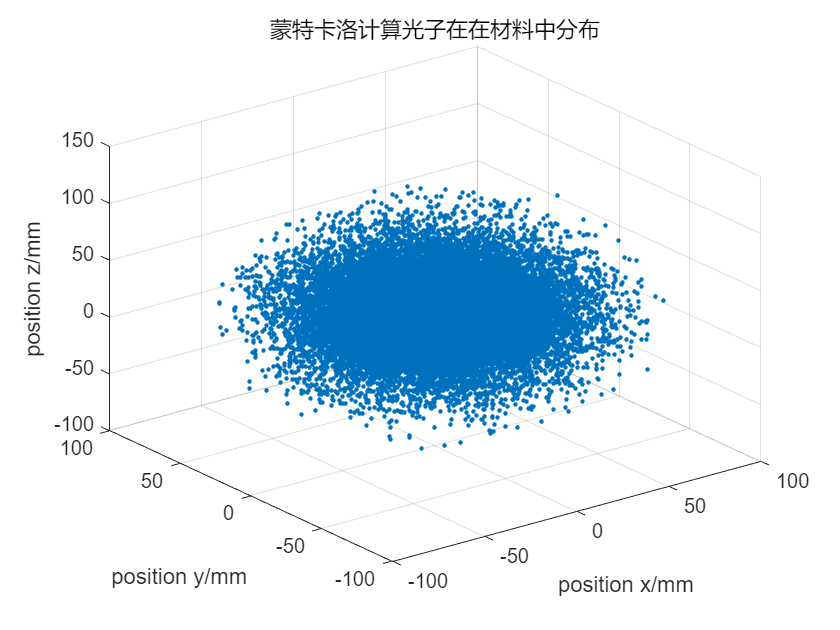

scatter3(X,Y,Z,5,'filled')
grid on;

xlabel('position x/mm ')
ylabel('position y/mm')
zlabel('position z/mm')
title('蒙特卡洛计算光子在在材料中分布')

## Meshing (2D-coordinate system of columns)

% 组织网格计算精度
voxel_dim_r=0.1;
voxel_dim_theta=(2*pi)/100;
voxel_dim_z=0.1;

% 组织网格计算范围
cal_rang_r_max=diameter*20/2;
cal_rang_r_min=diameter/2;
cal_rang_theta=2*pi;
cal_rang_z=cylinder_length*3;

% Coordinate system of columns
r=cal_rang_r_min:voxel_dim_r:cal_rang_r_max;
r_length=(cal_rang_r_max-cal_rang_r_min)/voxel_dim_r;

theta=0:voxel_dim_theta:2*pi;
theta_length=round((2*pi)/voxel_dim_theta);

z=0:voxel_dim_z:cal_rang_z;
z_length=(cal_rang_z)/voxel_dim_z;
% 坐标系转换笛卡尔-柱坐标
absorbed_photons_r = coordinate_conversion(absorbed_photons);

## Heat Source and Heat distribution (2D-coordinate system of columns)


$$E_{\text {photon }}=\frac{P_{\text {laser }} \Delta t}{N_{\text {photon }}}$$


Sum_Q_slide=Heat_distribution(r_length,theta_length,z_length,voxel_dim_r,voxel_dim_theta,voxel_dim_z,X,Y,Z,diameter,absorbed_photons_r);

Q_slide=Sum_Q_slide*power_per_photon;

## 温度测算

微分方程


$$\frac{\mathrm{dT}(\mathrm{r}, \mathrm{t})}{\mathrm{dt}}=\frac{\lambda}{\rho \mathrm{c}} \Delta \mathrm{T}(\mathrm{r}, \mathrm{t})+\frac{\mathrm{Q}(\mathrm{r}, \mathrm{t})}{\rho \mathrm{c}}-\rho v_{\mathrm{B}}\left(\mathrm{T}(\mathbf{r}, \mathrm{t})-\mathrm{T}_{\text {Averial }}\right)$$



$$\Delta=\frac{\delta^2}{\delta x^2}+\frac{\delta^2}{\delta y^2}+\frac{\delta^2}{\delta z^2} \quad \text { Laplace operator }$$



$$Q=\mu_{\mathrm{a}} \Psi(\mathrm{r}, \mathrm{t}) \quad \text { source term }\left[\mathrm{Wcm} \mathrm{cm}^{-3}\right]$$



$$v_{\mathrm{B}} \quad \text { perfusionrate }\left[\mathrm{mlg}^{-1} \mathrm{~min}^{-1}\right]$$


数值计算

The source term $$Q_{r, z}$$ for each voxel (centre co-ordinates $$r, z$$ ) was given by the number of absorbed photons $$\left(\mathrm{N}_{\text {absorbed }}\right)$$ the Energy of each photon $$\left(\mathrm{E}_{\text {photon }}\right)$$, the duration of a time interval of calculation $$(\Delta t)$$ and the individual voxel volume $$\left(V_{r, 2}\right)$$ :


$$Q_{r, z, t}=\frac{N_{\text {absorbed } r, z t} E_{\text {photon }}}{V_{r, z} \Delta t}$$


From these formulas the new temperature for each voxel and each time interval (before consideration of blood perfusion and heat conduction) was given by:


$$T_{r, z, t}=T_{r, z, t-\Delta t}+\frac{Q_{r, z, t} \Delta t}{\rho_{r, z, t} c_{r, z, t}}$$


The blood perfusion of the tissue was considered by an additional loss term as described in the bio heat equation. For the prostate a gland perfusion of$ $0.1 \mathrm{mlg}^{-1} \mathrm{~min}^{-1}$$ was assumed, while a perfusion of $$1.0 \mathrm{mlg}^{-1} \mathrm{~min}^{-1}$$ was applied for liver tissue $^{82}$. The perfusion was actually set to zero for those voxels where coagulation took place during the treatment. This was due to the shrinkage of capillary vessels corresponding with coagulation ${ }^{83,84}$. The resulting temperature for each voxel is:

for i6=0

end